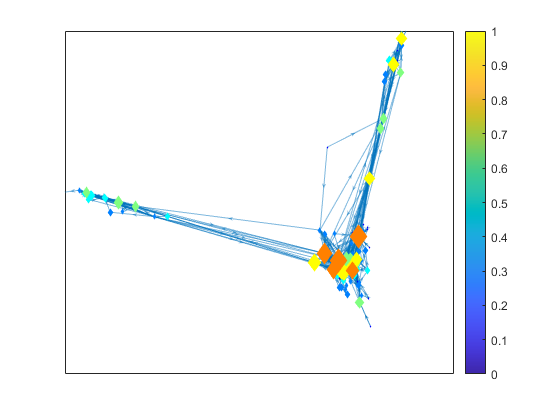

clear,clc
EdgeTable = readtable("g_edges.csv","Range",'A2:C550');
s = EdgeTable(:,1);
s = table2cell(s);
s = s';
t = EdgeTable(:,2);
t = table2cell(t);
t = t';
weight = EdgeTable(:,3);
weight = table2array(weight);
weight = weight';
G = digraph(s,t,weight);
%plot(G);%1
a = G.Nodes.Variables;
b = indegree(G,a);
c = sort(b,'descend');
Size = [];
max = {'','','','',''};
k = 1;
color = [b,b,b];
jt = jet(6);
for i = 1:numnodes(G)
    Size = [Size 2*sqrt(indegree(G,a(i)))+0.2];
    if b(i) >=c(5)
        max(k) = a(i);
        k = k+1;
    end
    if b(i) == 0
        color(i,:) = jt(1,:);
    elseif b(i) < 3
        color(i,:) = jt(2,:);
    elseif b(i) < 5
        color(i,:) = jt(3,:);
    elseif b(i) < 11
        color(i,:) = jt(4,:);
    elseif b(i) < 21
        color(i,:) = jt(5,:);
    else
        color(i,:) = jt(6,:);
    end
end
plot(G,"Marker","diamond","MarkerSize",Size,"NodeColor",color);
Path = shortestpath(G,'NED',"TYRION");%4
colorbar;